# Rotational Number Computation

clear all
close all
clc
interpreter = 'latex';
set(0,'defaulttextinterpreter',interpreter)

PLOT_TRAPPED = 'on'

PLOT_TRAPPED = 'on'

PLOT_DIFFUSIVE = 'off'

PLOT_DIFFUSIVE = 'off'

PLOT_BALLISTIC = 'on'

PLOT_BALLISTIC = 'on'

Grid            = 'on';
sizes           = [1.25, 2.5, 3.5];                  % 0.5 dots, square
col             = {'.b', '.m', '.k', '-g'};     % un, tr, square, thresh
font_sizes      = [25, 15];

load(dir('*.mat').name);
sy = {'$A$';'$\rho$';'$\eta$';'$R2$'};
caption = sprintf('%s = %.3f; %s = %.3f; %s = %.3f', char(sy(1)), A, char(sy(2)), rho, char(sy(3)), eta);
caption_Diff_Poincare = sprintf('$Diffusive$  ; %s = %.3f; %s = %.3f; %s = %.3f', char(sy(1)), A, char(sy(2)), rho, char(sy(3)), eta);

x_tr = [];
y_tr = [];
x_diff = [];
y_diff = [];
x_ball = [];
y_ball = [];

if strcmp(PLOT_TRAPPED, 'on')
    x_tr = data{1}.x;
    y_tr = data{1}.y;
end
if strcmp(PLOT_DIFFUSIVE, 'on')
    x_diff = data{2}.x;
    y_diff = data{2}.y;
end
if strcmp(PLOT_BALLISTIC, 'on')
    x_ball = data{3}.x;
    y_ball = data{3}.y;
end

x1=0;
x2=2*pi;
y1=0;
y2=2*pi;
xs = [x1, x2, x2, x1, x1];
ys = [y1, y1, y2, y2, y1];

rot_number_ball = ( x_ball(:,end)-x_ball(:,1)) / size(x_ball,2);

n = size(x_ball,2) / 2;

x_ball_1 = x_ball(:,1:n);

x_ball_2 = x_ball(:,n+1:end);


rot_number_ball_1 = ( x_ball_1(:,end)-x_ball_1(:,1)) / size(x_ball_1,2);
rot_number_ball_2 = ( x_ball_2(:,end)-x_ball_2(:,1)) / size(x_ball_2,2);



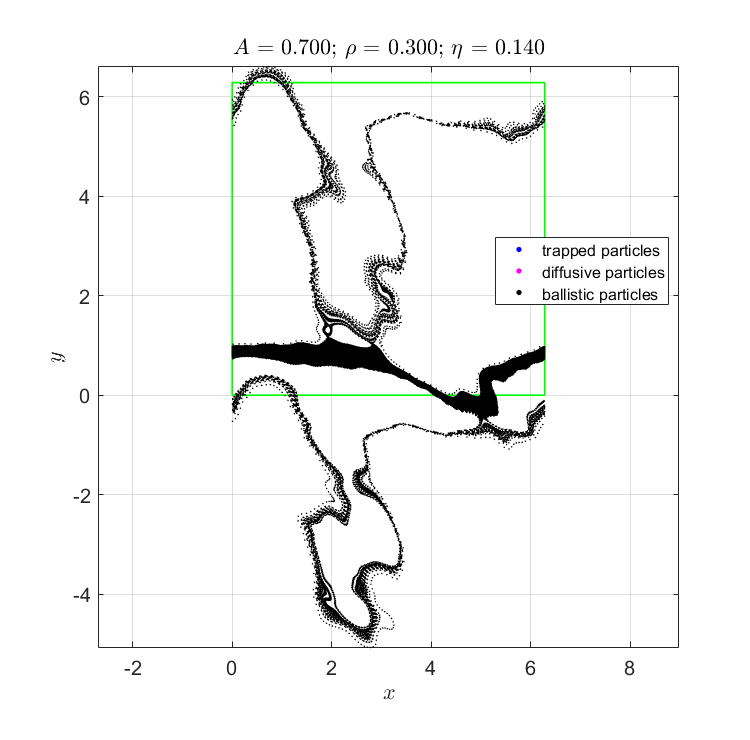

figure('Position', [5 30 750 740])
plot(xs, ys, char(col(4)), 'MarkerSize', sizes(2), 'LineWidth', sizes(1));
ax = gca;
ax.FontSize = 0.60*font_sizes(1);
axis vis3d
hold on
if strcmp(PLOT_TRAPPED, 'on')
    plot(x_tr.', y_tr.', char(col(1)), 'MarkerSize', sizes(1));
    %l1 = plot(nan, nan, char(col(1)));
    %legend([l1], {'trapped particles'},'location','best');
end
if strcmp(PLOT_DIFFUSIVE, 'on')
    plot(x_diff.', y_diff.', char(col(2)), 'MarkerSize', sizes(1));
    %l1 = plot(nan, nan, char(col(1)));
    %l2 = plot(nan, nan, char(col(2)));
    %legend([l1, l2], {'trapped particles', 'diffusive particles'},'location','best');
end
if strcmp(PLOT_BALLISTIC, 'on')
    plot(mod(x_ball,2*pi).', y_ball.', char(col(3)), 'MarkerSize', sizes(3));
    %plot(x_ball(1,:), y_ball(1,:), char(col(3)), 'MarkerSize', sizes(3));
end
l1 = plot(nan, nan, char(col(1)));
l2 = plot(nan, nan, char(col(2)));
l3 = plot(nan, nan, char(col(3)));
l1.MarkerSize = 12;
l2.MarkerSize = 12;
l3.MarkerSize = 12;
legend([l1, l2, l3], {'trapped particles', 'diffusive particles', 'ballistic particles'},'location','best','FontSize',12);
xlabel('$x$','FontSize',font_sizes(1))
ylabel('$y$','FontSize',font_sizes(1))
title(caption,'FontSize', font_sizes(2))
if strcmp(Grid,'on') == 1
    grid on
end
hold off

%%

%%

[y_ball(:,1), I] = sort(y_ball(:,1), 'ascend');
y_ball(:,2:end) = y_ball(I,2:end);
rot_number_ball(:) = rot_number_ball(I);
rot_number_ball_1(:) = rot_number_ball_1(I);
rot_number_ball_2(:) = rot_number_ball_2(I);
y0 = y_ball(:,1);

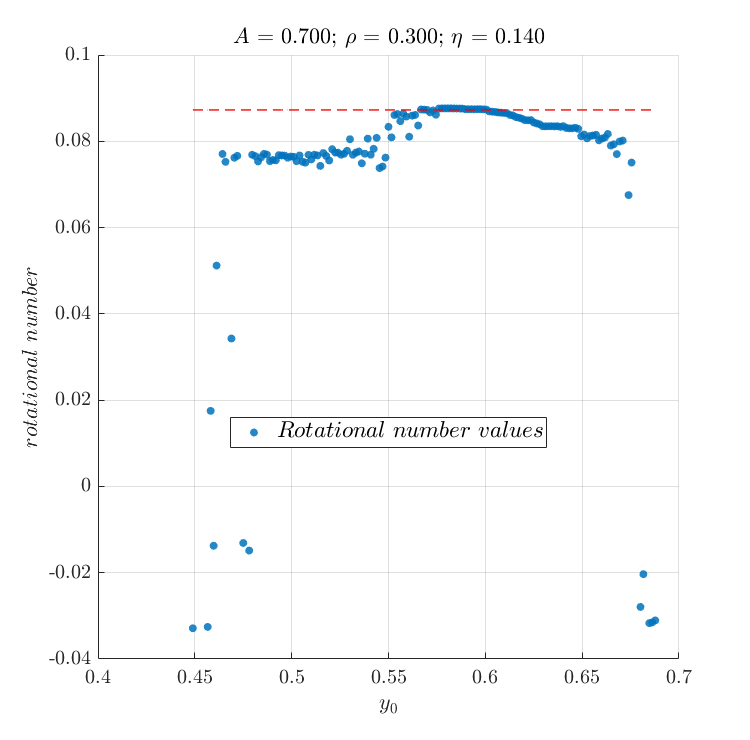

Cristel_hipothesis =ones(size(y0)) .*  (2*pi / 72);
figure('Position', [5 30 750 740])
ax = gca;
hold on
ax.FontSize = 0.60*font_sizes(1);
%axis vis3d
s = scatter(y0(:), rot_number_ball(:),[],'filled');
%distfromzero = sqrt((rot_number_ball - 0)^2);
%alpha(s,rot_number_ball);
s.MarkerFaceAlpha = 0.85;
plot(y0(:),Cristel_hipothesis(:),'--r','LineWidth',1);
legend([s(1)],"$Rotational~number~values$",'Location','best');
set(legend,'Interpreter','latex');
set(legend,'FontSize',17);
%plot(y0, rot_number_ball,':o', char(col(1)), 'MarkerSize', sizes(3))
xlabel('$y_0$','FontSize',font_sizes(1))
ylabel('$rotational~number$','FontSize',font_sizes(1))
%tick = double(2*pi/72);
%ytick = ([0 0.02 0.04 0.06 0.08 2*pi/72 0.1 0.12 0.14 0.16])
%yticks([0.05 tick 0.1]);
ax.TickLabelInterpreter='latex';
%testytick = ({'0.05','$\frac{2 pi}{72}$','0.1'})';
%testytick = ({'0','0.02','0.04','0.06','0.08','$\frac{2 pi}{72}','0.1','0.12','0.14','0.16'})
%yticklabels(testytick);
title(caption,'FontSize', font_sizes(2))
if strcmp(Grid,'on') == 1
    grid on
end
hold off

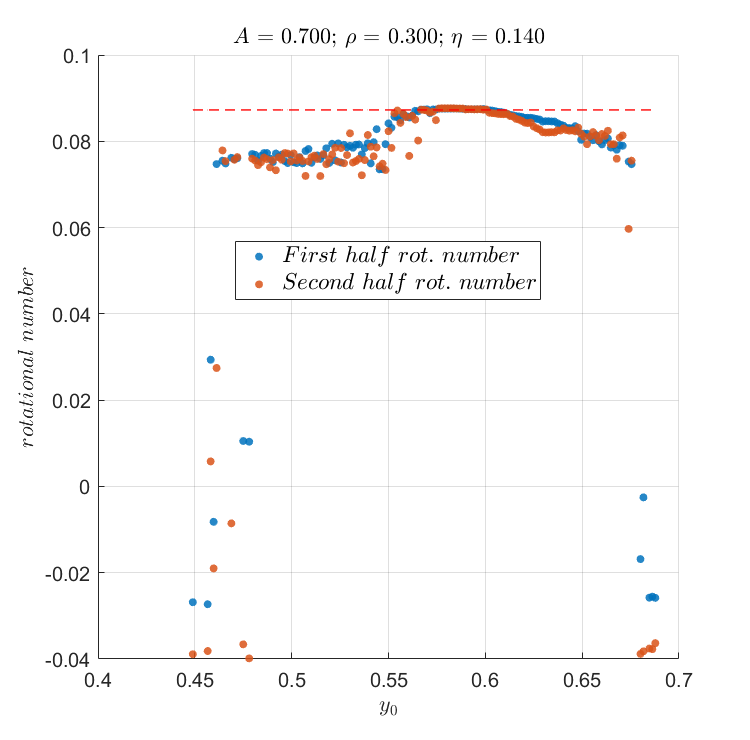

figure('Position', [5 30 750 740])
ax = gca;
hold on
ax.FontSize = 0.60*font_sizes(1);
%axis vis3d
s1 = scatter(y0(:), rot_number_ball_1(:),[],'filled');
s2 = scatter(y0(:), rot_number_ball_2(:),[],'filled');
%distfromzero = sqrt((rot_number_ball - 0)^2);
%alpha(s,rot_number_ball);
s1.MarkerFaceAlpha = 0.85;
s2.MarkerFaceAlpha = 0.85;
%plot(y0, rot_number_ball,':o', char(col(1)), 'MarkerSize', sizes(3))
plot(y0(:),Cristel_hipothesis(:),'--r','LineWidth',1);
legend([s1(1),s2(1)],"$First~half~rot.~number$","$Second~half~rot.~number$",'Location','best');
set(legend,'Interpreter','latex');
set(legend,'FontSize',17);
xlabel('$y_0$','FontSize',font_sizes(1))
ylabel('$rotational~number$','FontSize',font_sizes(1))
title(caption,'FontSize', font_sizes(2))
if strcmp(Grid,'on') == 1
    grid on
end
hold off

S = size(x_ball,2);
up_sum = S -1;

S1 = size(x_ball_1,2);
S2 = size(x_ball_2,2);
up_sum_1 = S1 -1;
up_sum_2 = S2 -1;

C_s = 0

C_s = 0

for n=1:up_sum
    app = bump_function(n,S);
    C_s = C_s + app;
end
%C_s

%rot_number_ball = ( x_ball(1,end)-x_ball(1,1)) / size(x_ball,2);
%rot_number_ball_func = rotational_number_function(S,x_ball(1,:));
W_B_s = 0;
for i=1:up_sum
    app = bump_function(i,S) * rotational_number_function(i,x_ball(:,:));
    W_B_s = W_B_s + app;
    if i == up_sum
        W_B_s = W_B_s / C_s;
    end
end
%W_B_s
W_B_s_1 = 0;
C_s_1 = 0;

for n=1:up_sum_1
    app = bump_function(n,S1);
    C_s_1 = C_s_1 + app;
end

for i=1:up_sum_1
    app = bump_function(i,S1) * rotational_number_function(i,x_ball_1(:,:));
    W_B_s_1 = W_B_s_1 + app;
    if i == up_sum_1
        W_B_s_1 = W_B_s_1 / C_s_1;
    end
end

W_B_s_2 = 0;
C_s_2 = 0;

for n=1:up_sum_2
    app = bump_function(n,S2);
    C_s_2 = C_s_2 + app;
end

for i=1:up_sum_2
    app = bump_function(i,S2) * rotational_number_function(i,x_ball_2(:,:));
    W_B_s_2 = W_B_s_2 + app;
    if i == up_sum_2
        W_B_s_2 = W_B_s_2 / C_s_2;
    end
end

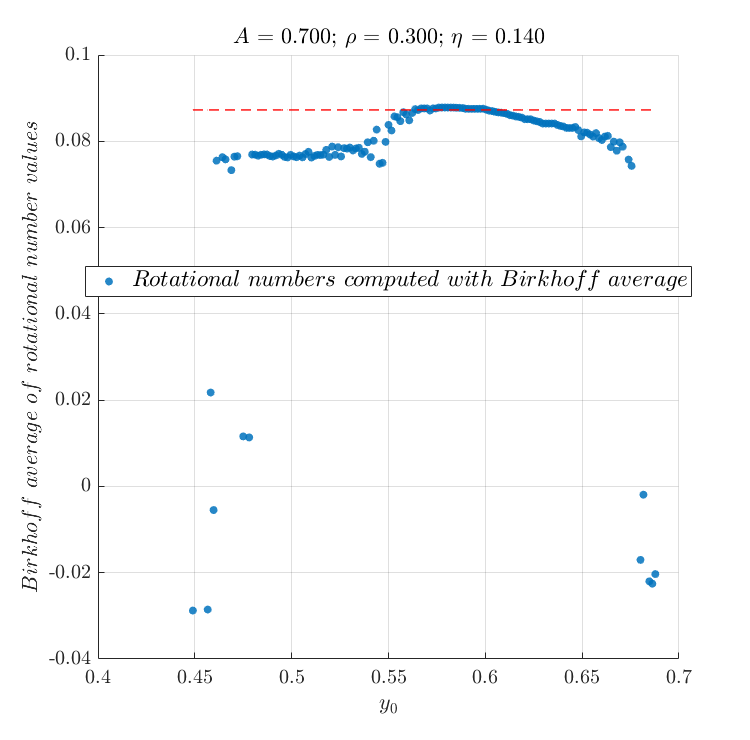

Cristel_hipothesis =ones(size(y0)) .*  (2*pi / 72);
figure('Position', [5 30 750 740])
ax = gca;
hold on
ax.FontSize = 0.60*font_sizes(1);
%axis vis3d
s = scatter(y0(:), W_B_s(:),[],'filled');
%distfromzero = sqrt((rot_number_ball - 0)^2);
%alpha(s,rot_number_ball);
s.MarkerFaceAlpha = 0.85;
plot(y0(:),Cristel_hipothesis(:),'--r','LineWidth',1);
legend([s(1)],"$Rotational~numbers~computed ~with~Birkhoff~average$",'Location','best');
set(legend,'Interpreter','latex');
set(legend,'FontSize',17);
%plot(y0, rot_number_ball,':o', char(col(1)), 'MarkerSize', sizes(3))
xlabel('$y_0$','FontSize',font_sizes(1))
ylabel('$Birkhoff~average~of~rotational~number~values$','FontSize',font_sizes(1))
%tick = double(2*pi/72);
%ytick = ([0 0.02 0.04 0.06 0.08 2*pi/72 0.1 0.12 0.14 0.16])
%yticks([0.05 tick 0.1]);
ax.TickLabelInterpreter='latex';
%testytick = ({'0.05','$\frac{2 pi}{72}$','0.1'})';
%testytick = ({'0','0.02','0.04','0.06','0.08','$\frac{2 pi}{72}','0.1','0.12','0.14','0.16'})
%yticklabels(testytick);
title(caption,'FontSize', font_sizes(2))
if strcmp(Grid,'on') == 1
    grid on
end
hold off

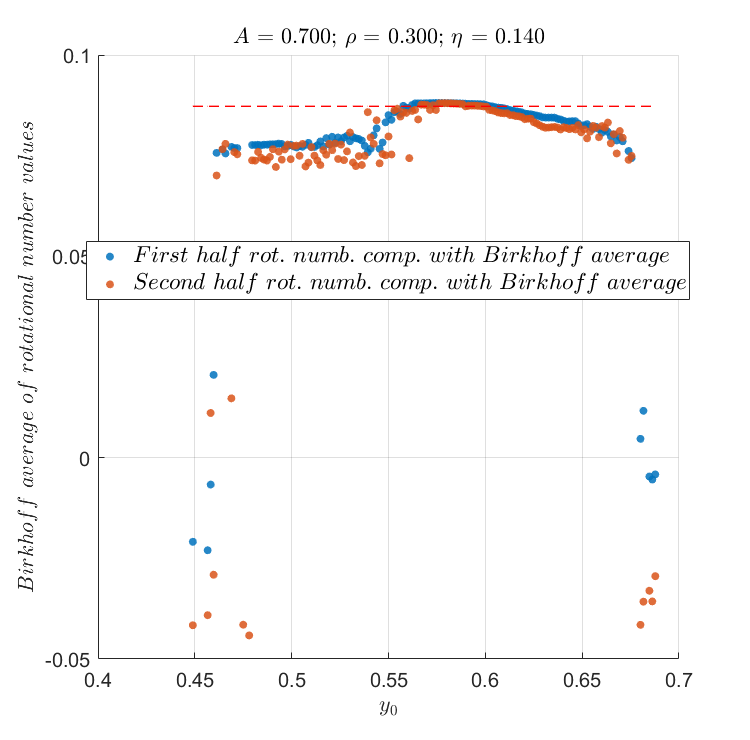

figure('Position', [5 30 750 740])
ax = gca;
hold on
ax.FontSize = 0.60*font_sizes(1);
%axis vis3d
s1 = scatter(y0(:), W_B_s_1(:),[],'filled');
s2 = scatter(y0(:), W_B_s_2(:),[],'filled');
%distfromzero = sqrt((rot_number_ball - 0)^2);
%alpha(s,rot_number_ball);
s1.MarkerFaceAlpha = 0.85;
s2.MarkerFaceAlpha = 0.85;
%plot(y0, rot_number_ball,':o', char(col(1)), 'MarkerSize', sizes(3))
plot(y0(:),Cristel_hipothesis(:),'--r','LineWidth',1);
legend([s1(1),s2(1)],"$First~half~rot.~numb.~comp.~with~Birkhoff~average$","$Second~half~rot.~numb.~comp.~with~Birkhoff~average$",'Location','best');
set(legend,'Interpreter','latex');
set(legend,'FontSize',17);
xlabel('$y_0$','FontSize',font_sizes(1))
ylabel('$Birkhoff~average~of~rotational~number~values$','FontSize',font_sizes(1))
title(caption,'FontSize', font_sizes(2))
if strcmp(Grid,'on') == 1
    grid on
end
hold off